%% demo_mpqp_loaded.mlx
clear; clc; close all;

%% ===================== Reproducibility note =====================
% This script evaluates five controllers on two mpQP benchmark settings:
%
%   QP:
%       The online teacher QP. It is rebuilt here from the public problem data.
%
%   PWA:
%       The explicit mpQP / PWA baseline. Since explicit-region construction
%       can be expensive or may timeout, this script uses the saved PWDeploy
%       object when pwa_status == "ok". It does not recompute the explicit
%       partition.
%
%   NN:
%       A pure neural-network baseline. The saved NNDeploy weights are used
%       for closed-loop/benchmark consistency.
%
%   NN+Proj:
%       The same NN followed by Euclidean projection onto the hard interface
%       S*xi + G*u <= h whenever the NN output violates the hard constraints.
%
%   Cert:
%       The proposed certified executor. The offline certified-library
%       construction toolbox is not included. A prebuilt deployment object is
%       loaded and evaluated online.
%
% The released XTrain/YTrain and XTest are included for transparency. The
% default benchmark uses saved Cert, NNDeploy, PWDeploy, and rebuilt QP/Proj.

%% ===================== Initialization =====================
rng(1);

%% ===================== Load release package =====================
release_mat = 'demo_mpqp_release_pack.mat';
load(release_mat, 'release_cfg', 'case1', 'case2');

solver_qp = release_cfg.solver_qp;
rho       = release_cfg.rho;
eps_s     = release_cfg.eps_s;
tol_viol  = release_cfg.tol_viol;

P1 = unpack_mpqp_case_(case1);
P2 = unpack_mpqp_case_(case2);

P1.Cert.mex_ready = false;
P1.Cert.mex_id    = [];
P2.Cert.mex_ready = false;
P2.Cert.mex_id    = [];

fprintf(['\n==================== MPQP LOADED DEMO ====================\n' ...
         '[Load] %s\n' ...
         '[S1] nu=%d, nxi=%d, neta=%d, XTrain=%d-by-%d, XTest=%d-by-%d, PWA=%s\n' ...
         '[S2] nu=%d, nxi=%d, neta=%d, XTrain=%d-by-%d, XTest=%d-by-%d, PWA=%s\n'], ...
         release_mat, ...
         P1.nu, P1.nxi, P1.neta, size(P1.XTrain, 1), size(P1.XTrain, 2), size(P1.XTest, 1), size(P1.XTest, 2), string(P1.pwa_status), ...
         P2.nu, P2.nxi, P2.neta, size(P2.XTrain, 1), size(P2.XTrain, 2), size(P2.XTest, 1), size(P2.XTest, 2), string(P2.pwa_status));


==================== MPQP LOADED DEMO ====================
[Load] demo_mpqp_release_pack.mat
[S1] nu=3, nxi=2, neta=1, XTrain=3-by-20000, XTest=3-by-5000, PWA=ok
[S2] nu=3, nxi=6, neta=2, XTrain=8-by-20000, XTest=8-by-5000, PWA=timeout



fprintf(['[Cert1] build=%.2fs, nFull=%d, nAct=%d, cover=%s\n' ...
         '[Cert2] build=%.2fs, nFull=%d, nAct=%d, cover=%s\n' ...
         '[NN1] train=%.2fs, mse_scaled=%.3e, mse_raw=%.3e\n' ...
         '[NN2] train=%.2fs, mse_scaled=%.3e, mse_raw=%.3e\n'], ...
         P1.cert_build_time, P1.cert_nFull, P1.cert_nAct, P1.cert_cover, ...
         P2.cert_build_time, P2.cert_nFull, P2.cert_nAct, P2.cert_cover, ...
         P1.nn_train_time, P1.nn_train_mse_s, P1.nn_train_mse_raw, ...
         P2.nn_train_time, P2.nn_train_mse_s, P2.nn_train_mse_raw);

[Cert1] build=179.77s, nFull=236, nAct=75, cover=certified
[Cert2] build=8216.25s, nFull=1935, nAct=436, cover=timeout
[NN1] train=22.14s, mse_scaled=1.511e-02, mse_raw=2.946e-02
[NN2] train=21.04s, mse_scaled=3.205e-02, mse_raw=4.172e-02



if strcmp(P1.pwa_status, "ok")
    fprintf('[PWA1] status=ok, solve=%.2fs, nCR=%d, mTot=%d\n', P1.pwa_time, P1.pwa_nCR, P1.pwa_mTot);
else
    fprintf('[PWA1] status=%s, solve=%.2fs\n', string(P1.pwa_status), P1.pwa_time);
end

[PWA1] status=ok, solve=1304.24s, nCR=12091, mTot=73642



if strcmp(P2.pwa_status, "ok")
    fprintf('[PWA2] status=ok, solve=%.2fs, nCR=%d, mTot=%d\n', P2.pwa_time, P2.pwa_nCR, P2.pwa_mTot);
else
    fprintf('[PWA2] status=%s, solve=%.2fs\n', string(P2.pwa_status), P2.pwa_time);
end

[PWA2] status=timeout, solve=7200.04s



%% ===================== Rebuild public QP and projection baselines =====================
ops_qp = sdpsettings('solver', solver_qp, 'verbose', 0);

P1 = build_oracles_(P1, rho, eps_s, ops_qp);
P2 = build_oracles_(P2, rho, eps_s, ops_qp);

fprintf('[QP] S1 min eig(H)=%.3e, S2 min eig(H)=%.3e\n', min(eig(P1.H)), min(eig(P2.H)));

[QP] S1 min eig(H)=8.231e-01, S2 min eig(H)=2.150e-01



%% ===================== Benchmark =====================
P1.out = benchmark_case_(P1);
P2.out = benchmark_case_(P2);

%% ===================== Report =====================
report_case_(P1, tol_viol);


==================== S1 REPORT ====================
PWA status = ok
----------------------------------------------------------------------------------------------------
Method    | time_us mean/p50/p99    | speedup    | proj use   | vmax/rate          | mse mean/p95      
----------------------------------------------------------------------------------------------------
QP        | 1188.92/1150.60/1626.65 |     1.00x |          - | 1.35e-08/  0.00% |        -
PWA       |  477.95/ 469.80/ 612.65 |     2.49x |          - | 8.89e-15/  0.00% | 7.81e-11/5.02e-13
NN        |    8.59/   8.00/  16.00 |   138.39x |          - | 5.06e-01/ 30.78% | 2.94e-02/8.51e-02
NN+Proj   |  295.27/   8.30/1218.35 |     4.03x |     30.84% | 1.78e-12/  0.00% | 2.82e-02/8.40e-02
Cert      |   33.02/  30.30/  66.20 |    36.01x |          - | 7.77e-16/  0.00% | 2.50e-02/7.54e-02
----------------------------------------------------------------------------------------------------


report_case_(P2, tol_viol);


==================== S2 REPORT ====================
PWA status = timeout
----------------------------------------------------------------------------------------------------
Method    | time_us mean/p50/p99    | speedup    | proj use   | vmax/rate          | mse mean/p95      
----------------------------------------------------------------------------------------------------
QP        | 1247.93/1220.10/1612.85 |     1.00x |          - | 1.13e-08/  0.00% |        -
NN        |    9.87/   9.30/  17.15 |   126.46x |          - | 3.50e-01/ 50.82% | 4.16e-02/1.44e-01
NN+Proj   |  477.67/ 849.70/1165.95 |     2.61x |     50.96% | 1.79e-11/  0.00% | 3.90e-02/1.42e-01
Cert      |   46.41/  42.90/  85.20 |    26.89x |          - | -2.22e-16/  0.00% | 3.34e-02/1.29e-01
----------------------------------------------------------------------------------------------------


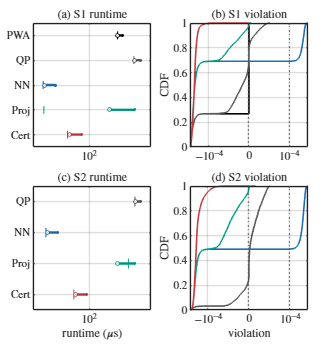


%% ===================== Plot =====================
fig = plot_mpqp_(P1.out, P2.out);

drawnow;
exportgraphics(fig, 'sim_mpQP.pdf', 'ContentType', 'vector');


pwa_policy_mex('clear');
nn_policy_mex('clear');

fprintf('[Plot] saved PDF: sim_mpQP.pdf\n');

[Plot] saved PDF: sim_mpQP.pdf



%% ===================== Local functions =====================
function P = unpack_mpqp_case_(Q)
    P = struct();

    P.id     = Q.id;
    P.nu     = Q.nu;
    P.nxi    = Q.nxi;
    P.neta   = Q.neta;
    P.d      = Q.d;
    P.mSoft  = Q.mSoft;

    P.Ah     = Q.Ah;
    P.bh     = Q.bh;
    P.Rhard  = Q.Rhard;
    P.z0     = Q.z0;

    P.S      = Q.S;
    P.G      = Q.G;
    P.h      = Q.h;

    P.Ss     = Q.Ss;
    P.Gs     = Q.Gs;
    P.Ts     = Q.Ts;
    P.hs     = Q.hs;

    P.H      = Q.H;
    P.F      = Q.F;
    P.Feta   = Q.Feta;
    P.f      = Q.f;

    P.XTrain = Q.XTrain;
    P.YTrain = Q.YTrain;
    P.XTest  = Q.XTest;

    P.Cert     = Q.Cert;
    P.NNDeploy = Q.NNDeploy;

    P.cert_build_time = Q.cert_build_time;
    P.cert_nFull      = Q.cert_nFull;
    P.cert_nAct       = Q.cert_nAct;
    P.cert_cover      = Q.cert_cover;

    P.nn_train_time    = Q.nn_train_time;
    P.nn_train_mse_s   = Q.nn_train_mse_s;
    P.nn_train_mse_raw = Q.nn_train_mse_raw;
    P.nn_stop_epoch    = Q.nn_stop_epoch;

    P.pwa_status = string(Q.pwa_status);
    P.pwa_time   = Q.pwa_time;
    P.PWDeploy   = Q.PWDeploy;
    P.pwa_nCR    = Q.pwa_nCR;
    P.pwa_mTot   = Q.pwa_mTot;
end

function P = build_oracles_(P, rho, eps_s, ops_qp)
    [xi, eta, u, s] = deal(sdpvar(P.nxi, 1), sdpvar(P.neta, 1), sdpvar(P.nu, 1), sdpvar(P.mSoft, 1));

    C = [
        P.S * xi + P.G * u <= P.h
        P.Ss * xi + P.Gs * u + P.Ts * eta <= P.hs + s
        s >= 0
    ];

    J = 0.5 * u.' * P.H * u + (P.F * xi + P.Feta * eta + P.f).' * u + rho * sum(s) + eps_s * (s.' * s);

    P.OPqp = optimizer(C, J, ops_qp, {xi, eta}, u);

    [xi, uhat, u] = deal(sdpvar(P.nxi, 1), sdpvar(P.nu, 1), sdpvar(P.nu, 1));

    P.OPproj = optimizer(P.S * xi + P.G * u <= P.h, (u - uhat).' * (u - uhat), ops_qp, {xi, uhat}, u);
end

function out = benchmark_case_(P)
    N      = size(P.XTest, 2);
    usePWA = strcmp(P.pwa_status, "ok") && ~isempty(P.PWDeploy);

    out.timing_us.qp  = nan(N, 1);
    out.timing_us.pwa = nan(N, 1);
    out.timing_us.nn  = nan(N, 1);
    out.timing_us.prj = nan(N, 1);
    out.timing_us.cn  = nan(N, 1);

    out.viol.qp  = nan(N, 1);
    out.viol.pwa = nan(N, 1);
    out.viol.nn  = nan(N, 1);
    out.viol.prj = nan(N, 1);
    out.viol.cn  = nan(N, 1);

    out.mse.pwa = nan(N, 1);
    out.mse.nn  = nan(N, 1);
    out.mse.prj = nan(N, 1);
    out.mse.cn  = nan(N, 1);
    out.proj_trigger = false(N, 1);

    nn_policy_mex('clear');
    nn_policy_mex('init', P.NNDeploy);

    if usePWA
        pwa_policy_mex('clear');
        pwa_policy_mex('init', P.PWDeploy);
    end

    tolProj = 1e-9;

    for i = 1:min(200, N)
        xi  = P.XTest(1:P.nxi, i);
        eta = P.XTest(P.nxi + 1:end, i);
        x   = P.XTest(:, i);
        rhs = P.h - P.S * xi;

        P.OPqp{xi, eta};

        if usePWA
            pwa_policy_mex('eval', x);
        end

        uNN = nn_policy_mex('eval', x);

        if any(P.G * uNN(:) > rhs + tolProj)
            P.OPproj{xi, uNN(:)};
        end

        P.Cert.cert_forward(xi, eta);
    end

    for i = 1:N
        xi  = P.XTest(1:P.nxi, i);
        eta = P.XTest(P.nxi + 1:end, i);
        x   = P.XTest(:, i);
        rhs = P.h - P.S * xi;

        t = tic;
        uQP = P.OPqp{xi, eta};
        out.timing_us.qp(i) = 1e6 * toc(t);
        uQP = uQP(:);

        if usePWA
            t = tic;
            uPWA = pwa_policy_mex('eval', x);
            out.timing_us.pwa(i) = 1e6 * toc(t);
            uPWA = uPWA(:);
        else
            uPWA = nan(P.nu, 1);
        end

        t = tic;
        uNN = nn_policy_mex('eval', x);
        out.timing_us.nn(i) = 1e6 * toc(t);
        uNN = uNN(:);

        t = tic;
        uHat = nn_policy_mex('eval', x);
        uHat = uHat(:);

        proj_hit = any(P.G * uHat > rhs + tolProj);
        out.proj_trigger(i) = proj_hit;

        if proj_hit
            uPrj = P.OPproj{xi, uHat};
            uPrj = uPrj(:);
        else
            uPrj = uHat;
        end

        out.timing_us.prj(i) = 1e6 * toc(t);

        t = tic;
        uCN = P.Cert.cert_forward(xi, eta);
        out.timing_us.cn(i) = 1e6 * toc(t);
        uCN = uCN(:);

        out.viol.qp(i)  = max(P.G * uQP - rhs);
        out.viol.pwa(i) = max(P.G * uPWA - rhs);
        out.viol.nn(i)  = max(P.G * uNN - rhs);
        out.viol.prj(i) = max(P.G * uPrj - rhs);
        out.viol.cn(i)  = max(P.G * uCN - rhs);

        out.mse.pwa(i) = mean((uPWA - uQP).^2);
        out.mse.nn(i)  = mean((uNN - uQP).^2);
        out.mse.prj(i) = mean((uPrj - uQP).^2);
        out.mse.cn(i)  = mean((uCN - uQP).^2);
    end
end

function report_case_(P, tol)
    out    = P.out;
    usePWA = has_pwa_(out);
    tOpt   = out.timing_us.qp;

    fprintf(['\n==================== S%d REPORT ====================\n' ...
         'PWA status = %s\n' ...
         '----------------------------------------------------------------------------------------------------\n' ...
         '%-9s | %-23s | %-10s | %-10s | %-18s | %-18s\n' ...
         '----------------------------------------------------------------------------------------------------\n'], ...
         P.id, string(P.pwa_status), 'Method', 'time_us mean/p50/p99', 'speedup', 'proj use', 'vmax/rate', 'mse mean/p95');

    print_row_('QP', out.timing_us.qp, out.viol.qp, [], tol, tOpt, []);

    if usePWA
        print_row_('PWA', out.timing_us.pwa, out.viol.pwa, out.mse.pwa, tol, tOpt, []);
    end

    print_row_('NN', out.timing_us.nn, out.viol.nn, out.mse.nn, tol, tOpt, []);
    print_row_('NN+Proj', out.timing_us.prj, out.viol.prj, out.mse.prj, tol, tOpt, out.proj_trigger);
    print_row_('Cert', out.timing_us.cn, out.viol.cn, out.mse.cn, tol, tOpt, []);

    fprintf('----------------------------------------------------------------------------------------------------\n');
end

function print_row_(name, t, v, mse, tol, tOpt, projTrigger)
    t    = t(isfinite(t));
    tOpt = tOpt(isfinite(tOpt));

    tMean   = mean(t);
    tP50    = prctile(t, 50);
    tP99    = prctile(t, 99);
    speedup = mean(tOpt) / tMean;

    if isempty(projTrigger)
        projStr = '-';
    else
        projStr = sprintf('%.2f%%', 100 * mean(projTrigger));
    end

    if isempty(mse)
        fprintf('%-9s | %7.2f/%7.2f/%7.2f | %8.2fx | %10s | %8.2e/%6.2f%% | %8s\n', ...
            name, tMean, tP50, tP99, speedup, projStr, max(v), 100 * mean(v > tol), '-');
    else
        fprintf('%-9s | %7.2f/%7.2f/%7.2f | %8.2fx | %10s | %8.2e/%6.2f%% | %8.2e/%8.2e\n', ...
            name, tMean, tP50, tP99, speedup, projStr, max(v), 100 * mean(v > tol), mean(mse), prctile(mse, 95));
    end
end

function fig = plot_mpqp_(out1, out2)
    cfg     = plot_cfg_();
    usePWA1 = has_pwa_(out1);
    usePWA2 = has_pwa_(out2);

    cfg.timing_xlim = timing_xlim_({out1, out2}, [usePWA1, usePWA2]);

    fig = figure('Color', 'w', 'Units', 'inches', ...
        'Position', [1, 1, cfg.fig_w, cfg.fig_h], ...
        'Renderer', 'painters');

    tl = tiledlayout(2, 2, ...
        'Padding', 'compact', ...
        'TileSpacing', 'compact');

    ax11 = nexttile(tl, 1);
    setup_ax_(ax11, cfg);
    plot_timing_summary_(ax11, out1, usePWA1, cfg);
    title(ax11, '(a) S1 runtime', 'Interpreter', 'latex');

    ax12 = nexttile(tl, 2);
    setup_ax_(ax12, cfg);
    plot_viol_cdf_(ax12, out1, usePWA1, cfg);
    title(ax12, '(b) S1 violation', 'Interpreter', 'latex');
    ylabel(ax12, 'CDF', 'Interpreter', 'latex');

    ax21 = nexttile(tl, 3);
    setup_ax_(ax21, cfg);
    plot_timing_summary_(ax21, out2, usePWA2, cfg);
    title(ax21, '(c) S2 runtime', 'Interpreter', 'latex');
    xlabel(ax21, 'runtime ($\mu$s)', 'Interpreter', 'latex');

    ax22 = nexttile(tl, 4);
    setup_ax_(ax22, cfg);
    plot_viol_cdf_(ax22, out2, usePWA2, cfg);
    title(ax22, '(d) S2 violation', 'Interpreter', 'latex');
    xlabel(ax22, 'violation', 'Interpreter', 'latex');
    ylabel(ax22, 'CDF', 'Interpreter', 'latex');
end

function cfg = plot_cfg_()
    cfg = struct();

    [cfg.fig_w, cfg.fig_h, cfg.fs] = deal(3.4, 3.6, 8);
    [cfg.cdf_lw, cfg.cert_lw]     = deal(0.9, 1.35);
    [cfg.bar_lw, cfg.tick_lw]     = deal(1.8, 0.8);
    cfg.cdf_lw = 1.2;
    [cfg.v0, cfg.vmark]           = deal(1e-12, 1e-4);

    cfg.color.qp  = [0.35 0.35 0.35];
    cfg.color.pwa = [0.00 0.00 0.00];
    cfg.color.nn  = [0.12 0.44 0.70];
    cfg.color.prj = [0.00 0.62 0.52];
    cfg.color.cn  = [0.78 0.24 0.26];
end

function setup_ax_(ax, cfg)
    hold(ax, 'on');
    box(ax, 'on');
    grid(ax, 'on');

    set(ax, ...
        'FontSize', cfg.fs, ...
        'TickLabelInterpreter', 'latex', ...
        'LineWidth', 0.6, ...
        'TickLength', [0.016 0.016], ...
        'XMinorGrid', 'off', ...
        'YMinorGrid', 'off', ...
        'GridAlpha', 0.15, ...
        'Layer', 'top');
end

function plot_timing_summary_(ax, out, usePWA, cfg)
    [names, keys, T] = timing_cells_(out, usePWA);
    Q = nan(numel(T), 3);

    for k = 1:numel(T)
        x       = T{k}(isfinite(T{k}) & T{k} > 0);
        Q(k, :) = [mean(x), prctile(x, 50), prctile(x, 99)];
    end

    y = (1:numel(names)).';

    for k = 1:numel(names)
        c     = color_(keys{k}, cfg);
        tMean = Q(k, 1);
        tP50  = Q(k, 2);
        tP99  = Q(k, 3);

        plot(ax, [tMean, tP99], [y(k), y(k)], '-', ...
            'Color', c, ...
            'LineWidth', cfg.bar_lw, ...
            'HandleVisibility', 'off');

        plot(ax, [tP50, tP50], [y(k) - 0.16, y(k) + 0.16], '-', ...
            'Color', c, ...
            'LineWidth', cfg.tick_lw, ...
            'HandleVisibility', 'off');

        plot(ax, tMean, y(k), 'o', ...
            'Color', c, ...
            'MarkerFaceColor', 'w', ...
            'MarkerSize', 2.8, ...
            'LineWidth', 0.7, ...
            'HandleVisibility', 'off');

        plot(ax, tP99, y(k), '.', ...
            'Color', c, ...
            'MarkerSize', 7, ...
            'HandleVisibility', 'off');
    end

    set(ax, ...
        'YDir', 'reverse', ...
        'YTick', y, ...
        'YTickLabel', names, ...
        'TickLabelInterpreter', 'latex', ...
        'XScale', 'log', ...
        'XLim', cfg.timing_xlim, ...
        'YLim', [0.5, numel(names) + 0.5]);
end

function plot_viol_cdf_(ax, out, usePWA, cfg)
    keys = {'qp', 'nn', 'prj', 'cn'};
    V    = {out.viol.qp, out.viol.nn, out.viol.prj, out.viol.cn};

    if usePWA
        keys = [{'pwa'}, keys];
        V    = [{out.viol.pwa}, V];
    end

    for k = 1:numel(V)
        x = sort(signedlog10_(V{k}(isfinite(V{k})), cfg.v0));
        y = (1:numel(x)).' / numel(x);

        stairs(ax, x, y, ...
            'LineStyle', '-', ...
            'LineWidth', cfg.cdf_lw, ...
            'Color', color_(keys{k}, cfg), ...
            'HandleVisibility', 'off');
    end

    xline(ax, 0, ':', ...
        'Color', [0.35 0.35 0.35], ...
        'LineWidth', 0.7, ...
        'HandleVisibility', 'off');

    xline(ax, signedlog10_(cfg.vmark, cfg.v0), ':', ...
        'Color', [0.35 0.35 0.35], ...
        'LineWidth', 0.7, ...
        'HandleVisibility', 'off');

    set(ax, 'YLim', [0 1]);
    set_signedlog_xticks_(ax, cfg.v0, cfg.vmark);
end

function [names, keys, T] = timing_cells_(out, usePWA)
    names = {'QP', 'NN', 'Proj', 'Cert'};
    keys  = {'qp', 'nn', 'prj', 'cn'};
    T     = {out.timing_us.qp, out.timing_us.nn, out.timing_us.prj, out.timing_us.cn};

    if usePWA
        names = [{'PWA'}, names];
        keys  = [{'pwa'}, keys];
        T     = [{out.timing_us.pwa}, T];
    end
end

function xl = timing_xlim_(outs, usePWA)
    vals = [];

    for i = 1:numel(outs)
        [~, ~, T] = timing_cells_(outs{i}, usePWA(i));

        for k = 1:numel(T)
            vals = [vals; T{k}(:)];
        end
    end

    vals = vals(isfinite(vals) & vals > 0);

    if isempty(vals)
        xl = [1, 1e4];
    else
        xl = [0.75 * min(vals), 1.25 * max(vals)];
    end
end

function tf = has_pwa_(out)
    tf = any(isfinite(out.timing_us.pwa)) && any(isfinite(out.viol.pwa)) && any(isfinite(out.mse.pwa));
end

function c = color_(key, cfg)
    c = cfg.color.(key);
end

function x = signedlog10_(v, v0)
    x = sign(v) .* log10(1 + abs(v) ./ v0);
end

function set_signedlog_xticks_(ax, v0, mark)
    ticks = signedlog10_([-mark, 0, mark], v0);

    set(ax, ...
        'XTick', ticks, ...
        'XTickLabel', {sprintf('$-10^{%d}$', round(log10(mark))), '$0$', sprintf('$10^{%d}$', round(log10(mark)))}, ...
        'TickLabelInterpreter', 'latex');
end  